addpath('functions/');

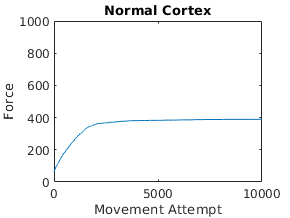

% Creating n Corticalspinal cells
n = 1000; 

% Initalize the base CS cells
% 80% of the n Cortical cells are M1
m1_count = n * 0.8;
m1_destroyed = m1_count * 0.8;
m1_alive = m1_count * 0.2;
m1 = [zeros(1, m1_destroyed), rand(1, m1_alive)];
% 20& of the n Cortical cells are SMA
sma_count = n * 0.2;
sma = rand(1, sma_count);

x_0 = [m1, sma];

% Parameters for zero-mean normal distribution
std_dev = 0.02;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_w = create_cs(0.7, n); 
extensor_c_w = create_cs(0.3, n); 

% Translating MN pool to force
delta = 1;

forces = [];
final_forces = [];
trials = [];
f_final_net = 0;
max_trials = 10000;
for trial = 1:max_trials
    v_i = std_dev.*randn(1, n) + mean;
    x_i = x_0 + v_i;
    for i = 1:m1_destroyed
        % Ensure CS M1 cells are destroyed (0)
        x_i(i) = 0;
    end

    % Flexor MN Pools translated to force
    s_fi = 0;
    for i = 1:n
        if i > 0.8 * n
            % SMA
            s_fi = s_fi + (0.1 * g_i(x_i(i), flexor_c_w(i)));
        else
            % M1
            s_fi = s_fi + g_i(x_i(i), flexor_c_w(i));
        end
    end
    f_f = delta * s_fi;
    
    % Extensor MN Pools translated to force
    s_ei = 0;
    for i = 1:n
        if i > 0.8 * n
            % SMA
            s_ei = s_ei + (0.1 * g_i(x_i(i), extensor_c_w(i)));
        else
            % M1
            s_ei = s_ei +  g_i(x_i(i), extensor_c_w(i));
        end
    end
    f_e = delta * s_ei;

    % Net force
    f_net = f_f - f_e;

    if f_net > f_final_net
        f_final_net = f_net;
        x_0 = x_i;
    end

    trials = [trials, trial];
    final_forces = [final_forces, f_final_net];
end

plot(trials, final_forces)
title("80% of M1 Destroyed")
ylim([0, n])
ylabel('Force')
xlabel('Movement Attempt')

saveas(gcf,'images/M1Destroyed80.png')

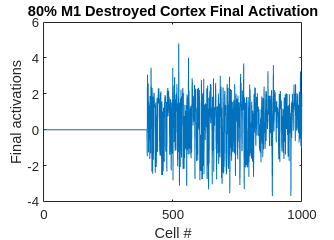

plot(x_0)
hold on
plot(10 * ones(1, m1_count))
hold off
title("80% M1 Destroyed Cortex Final Activation")
ylim([0, 15])
ylabel("Final activations")
xlabel("Cell #")

saveas(gcf, 'images/M1Destroyed80Activations.png')